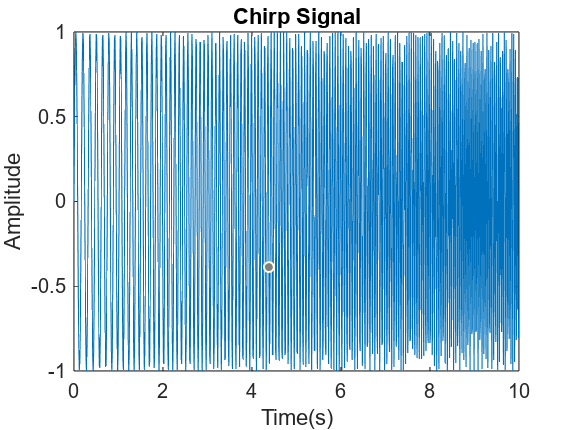

alpha = 1 + mod(202,3);
t = 0:1/100:(10-1/100);
f = linspace(6,15,1000);
x = sin(2*pi.*f.*t);
figure(1)
plot(t,x)
title("Chirp Signal")
xlabel('Time(s)')
ylabel('Amplitude')

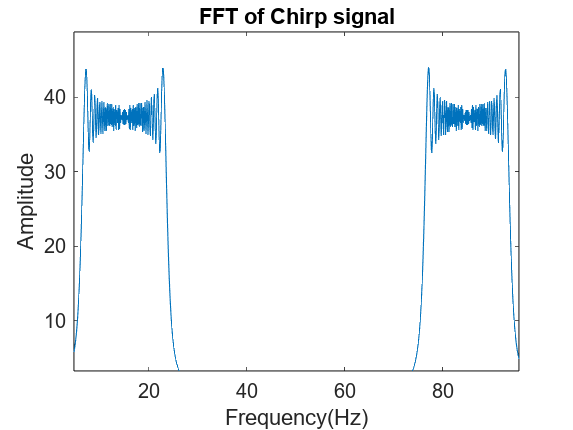

m = abs(fft(x));
F = (0:length(m)-1)*100/length(m);
figure(2)
plot(F,m)
title('FFT of Chirp signal')
xlabel("Frequency(Hz)");
ylabel("Amplitude");

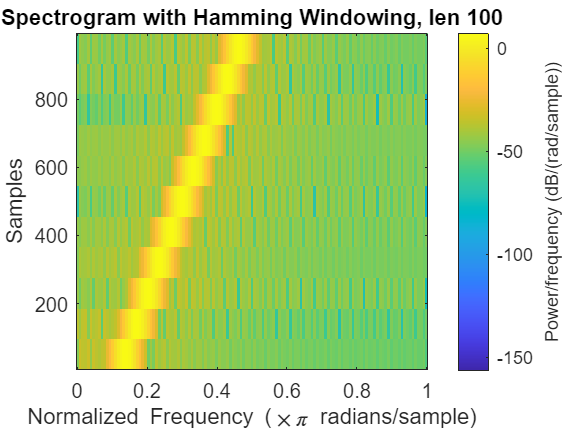


% Spectrogram parameters
window_length = 100; % Length of the Hamming window (samples)
overlap = 10;        % Overlap between consecutive windows (samples)
window_length_2 = 200;

% Create and plot the spectrogram
figure(3);
spectrogram(x, hamming(window_length), overlap);
title('Spectrogram with Hamming Windowing, len 100');

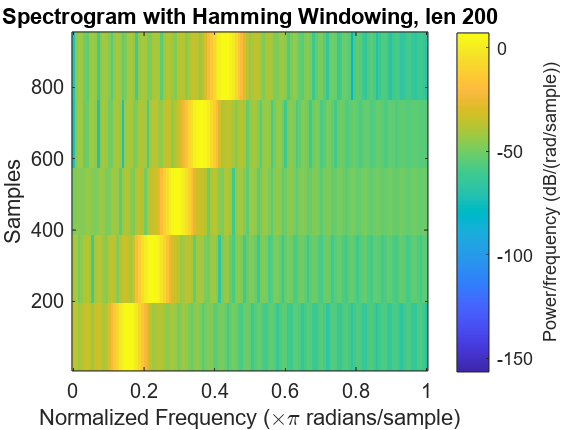

figure(4);
spectrogram(x, hamming(window_length_2), overlap);
title('Spectrogram with Hamming Windowing, len 200');

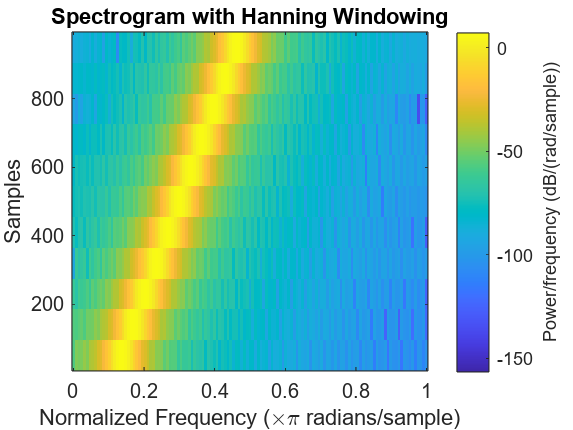

figure(5);
spectrogram(x, hanning(window_length), overlap);
title('Spectrogram with Hanning Windowing');

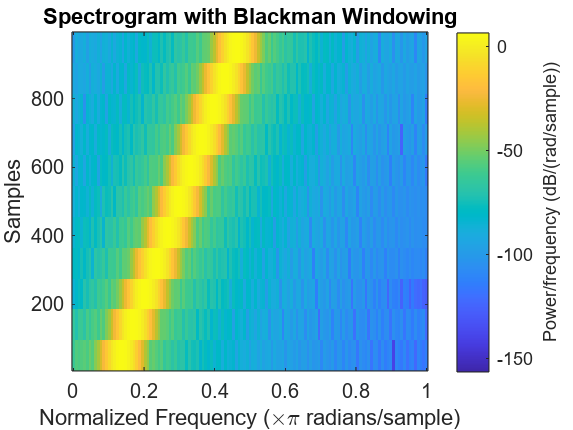

figure(6);
spectrogram(x, blackman(window_length), overlap);
title('Spectrogram with Blackman Windowing');